## Load measured data

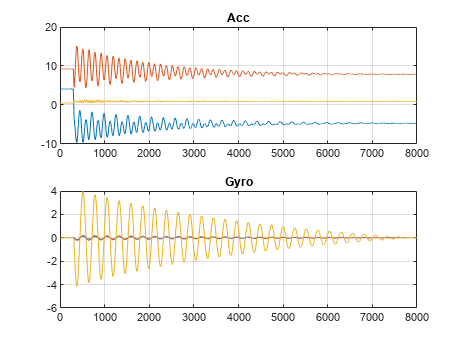

clear all
load data_28_11_2022\data_imu_kyvadlo_dynamic7.mat
sample_rate=200;    

subplot(2,1,1);
plot(dataAcc);grid;title('Acc');
subplot(2,1,2);
plot(dataGyro);grid;title('Gyro');


gyroSignal = (dataGyro(301:end,3));


## Read damping & freq

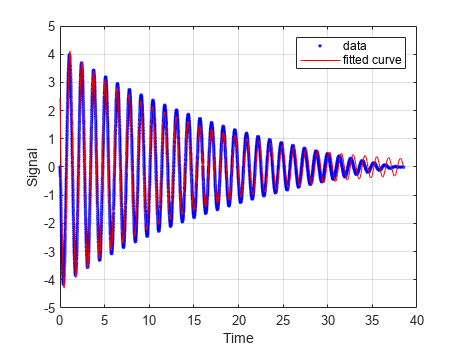

fitresult =      General model:
     fitresult(t) = exp(-b.*((w)./(sqrt(1-(b.^2)))).*t).*A.*sin((w).*t+p)
     Coefficients (with 95% confidence bounds):
       A =      -4.439  (-4.477, -4.4)
       b =     0.01476  (0.01457, 0.01495)
       p =     -0.5803  (-0.5888, -0.5718)
       w =       4.751  (4.75, 4.752)

gof = struct with fields:
           sse: 997.5050
       rsquare: 0.9325
           dfe: 7696
    adjrsquare: 0.9325
          rmse: 0.3600


time_vector=(0:5:5*length(gyroSignal)-1)'/1000;
[fitresult, gof] = createFit(time_vector, gyroSignal)


omega=fitresult.w

omega = 4.7510

frek=omega/(2*pi)

frek = 0.7562

b_r=fitresult.b

b_r = 0.0148

## FFT (kontrola frekvence)

Y=fft(gyroSignal);
L=length(Y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
f = sample_rate*(0:(L/2))/L;
% plot(f,P1)
[m,inx]=max(P1);
frek2=f(inx)

frek2 = 0.7532

omega2=2*pi*frek2

omega2 = 4.7328

## Predpis trajektorie

% t = (0:0.005:0.005);
omb = 2*pi*frek;
om = omb/sqrt(1-b_r^2);
phi0 = asin(147/180);
A=phi0;B=(b_r*om*phi0)/omb;    %<--- dx0=0, x0=phi0 KONTROLA!
phi_math=exp(-b_r*om*time_vector).*(A*cos(omb*time_vector)+B*sin(omb*time_vector));


## Kalman

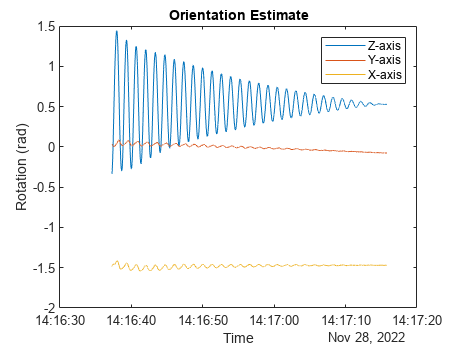

fusion_decimation_factor=1;
filter = imufilter('SampleRate',sample_rate,'DecimationFactor',fusion_decimation_factor,'OrientationFormat','Rotation matrix');
filter.AccelerometerNoise=1e-3;
filter.GyroscopeNoise=1e-2;

rot_matrices = filter(dataAcc(301:end,:),dataGyro(301:end,:));

timesAfterFuse=dataTimestamps(301:fusion_decimation_factor:end);
plot(timesAfterFuse,rotm2eul(rot_matrices))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis') 
xlabel('Time')
ylabel('Rotation (rad)')

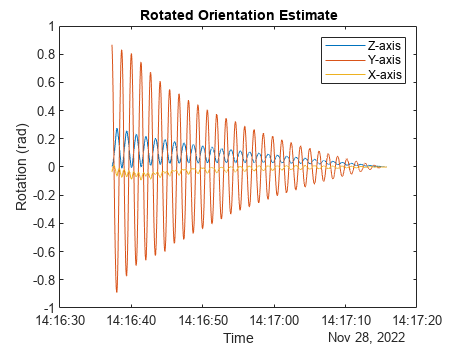

% draw_3D_poseplot(rot_matrices);

R = rot_matrices(:,:,end)';%*[0 1 0;0 0 -1;-1 0 0]';
for i = 1:size(rot_matrices,3)
    rot_matrices_rot(:,:,i)=R*rot_matrices(:,:,i);
end
figure
plot(timesAfterFuse,rotm2eul(rot_matrices_rot))
title('Rotated Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time')
ylabel('Rotation (rad)')

% draw_3D_poseplot(rot_matrices);


## Porovnání orientací

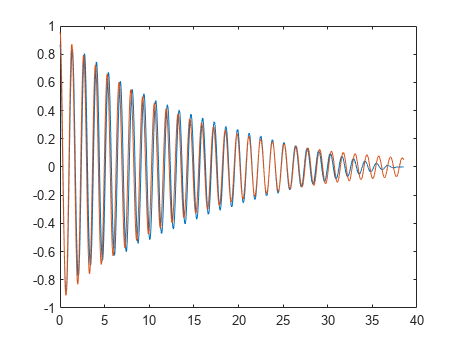

eul=rotm2eul(rot_matrices_rot);
phi_kalman=eul(:,2);
plot(time_vector,phi_kalman);
hold on
plot(time_vector,phi_math)
hold off

## Kalibrace

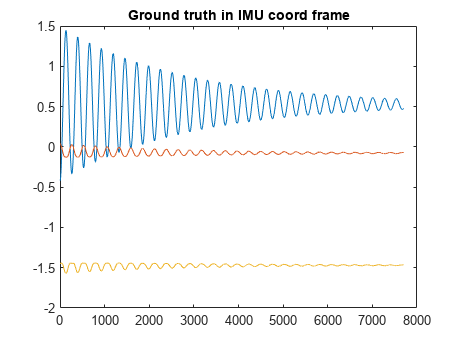

Accelerometer=dataAcc(301:end,:);
Gyroscope=dataGyro(301:end,:);
sensorData=table(Accelerometer,Gyroscope);

truth_rot=eul2rotm([zeros(length(phi_math),1) phi_math zeros(length(phi_math),1)]);
for i = 1:size(truth_rot,3)
    truth_rot(:,:,i)=R'*truth_rot(:,:,i);
end
plot(rotm2eul(truth_rot));title('Ground truth in IMU coord frame');

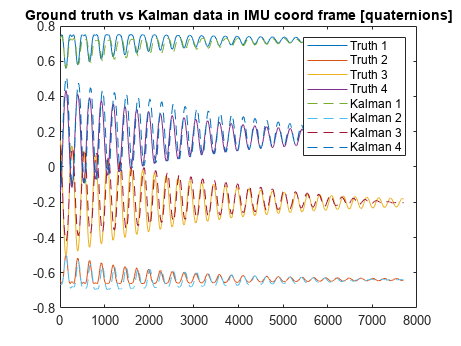


figure;plot(rotm2quat(truth_rot));hold on;plot(rotm2quat(rot_matrices),'--');hold off; title('Ground truth vs Kalman data in IMU coord frame [quaternions]');legend('Truth 1','Truth 2','Truth 3','Truth 4','Kalman 1','Kalman 2','Kalman 3','Kalman 4');


Orientation=quaternion(rotm2quat(truth_rot));
groundTruthTraj = table(Orientation);

% %FAKES
% Accelerometer=[dataAcc(301:end,:);dataAcc(end:-1:301,:)];
% Gyroscope=[dataGyro(301:end,:);dataGyro(end:-1:301,:)];
% sensorData=table(Accelerometer,Gyroscope);
% fake_truth_rot = rotm2quat(truth_rot);
% Orientation=quaternion([fake_truth_rot;fake_truth_rot(end:-1:1,:)]);
% groundTruthTraj = table(Orientation);

reset(filter)
config=tunerconfig("imufilter","MaxIterations",20,"ObjectiveLimit",0.001);
tune(filter,sensorData,groundTruthTraj,config)

    Iteration    Parameter                        Metric
    _________    _________                        ______
    1            AccelerometerNoise               2.9536
    1            GyroscopeNoise                   2.9525
    1            GyroscopeDriftNoise              2.9525
    1            LinearAccelerationNoise          2.9507
    1            LinearAccelerationDecayFactor    2.9490
    2            AccelerometerNoise               2.9488
    2            GyroscopeNoise                   2.9481
    2            GyroscopeDriftNoise              2.9481
    2            LinearAccelerationNoise          2.9467
    2            LinearAccelerationDecayFactor    2.9434
    3            AccelerometerNoise               2.9432
    3            GyroscopeNoise                   2.9428
    3            GyroscopeDriftNoise              2.9428
    3            LinearAccelerationNoise          2.9417
    3            LinearAccelerationDecayFactor    2.93

## Použití nakalibrovaného filtru

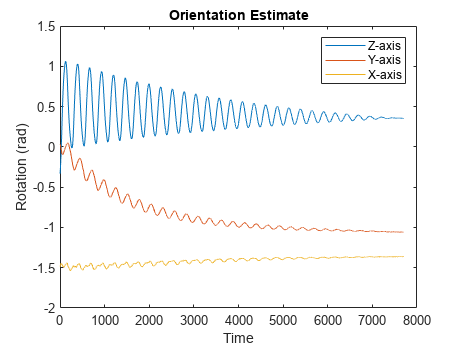

rot_matrices_calibrated = filter(dataAcc(301:end,:),dataGyro(301:end,:));

timesAfterFuse=dataTimestamps(301:fusion_decimation_factor:end);
plot(rotm2eul(rot_matrices_calibrated))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis') 
xlabel('Time')
ylabel('Rotation (rad)')

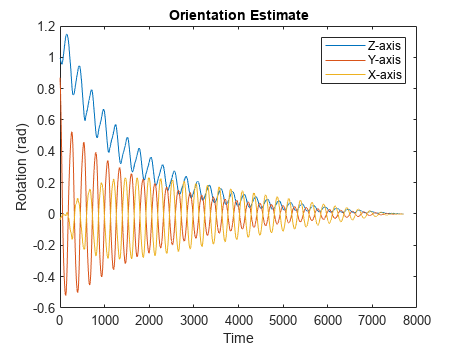

% draw_3D_poseplot(rot_matrices_calibrated);

RR = rot_matrices_calibrated(:,:,end)';
for i = 1:size(rot_matrices_calibrated,3)
    rot_matrices_calibrated_rot(:,:,i)=RR*rot_matrices_calibrated(:,:,i);
end
figure
plot(rotm2eul(rot_matrices_calibrated_rot))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time')
ylabel('Rotation (rad)')

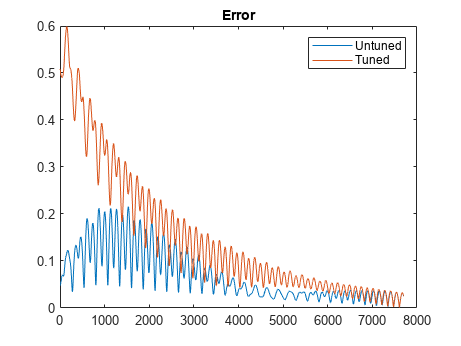

% draw_3D_poseplot(rot_matrices_calibrated);

figure;
plotPerformance(rot_matrices_rot,[zeros(length(phi_math),1) phi_math zeros(length(phi_math),1)]);hold on;
plotPerformance(rot_matrices_calibrated_rot,[zeros(length(phi_math),1) phi_math zeros(length(phi_math),1)]);legend('Untuned','Tuned');title('Error');hold off;